%Import data
fileLoc = "Optimisations456"

fileLoc = "Optimisations456"

names = dir(fileLoc);
names = string({names(:).name});
namesInd = endsWith(names, ".mat");
names = names(namesInd)

names = 1×3 string array
    "Optimisation4.mat"    "Optimisation5.mat"    "Optimisation6.mat"



allData = []


allData =

     []



indexs = [];

for i = 1:length(names)

data = load(fileLoc + "\" + names(i));
data = data.data;

RsCrit2 = cell2mat(data{3,2}.RsCrit2);
Maximisepeaknumber = cell2mat(data{3,2}.Maximisepeaknumber);
Minimisemethodtime = cell2mat(data{3,2}.Minimisemethodtime);
GradTime = data{2,2}.GradTime;
InitalOM = data{2,2}.InitalOM;
IsoHoldTime = data{2,2}.IsoHoldTime;

RsCrit2 = exp(-RsCrit2);
Maximisepeaknumber = round(exp(-Maximisepeaknumber),1);
Minimisemethodtime = exp(Minimisemethodtime);

index = (Maximisepeaknumber == 7) & (RsCrit2 >= 1.5);
%index = (Maximisepeaknumber == 7);

RsCrit2 = RsCrit2(index);
Maximisepeaknumber = Maximisepeaknumber(index);
Minimisemethodtime = Minimisemethodtime(index);
GradTime = GradTime(index);
InitalOM = InitalOM(index);
IsoHoldTime = IsoHoldTime(index);

allData = [allData;
            RsCrit2 Maximisepeaknumber Minimisemethodtime (ones(length(RsCrit2), 1)*i)+21 GradTime InitalOM IsoHoldTime];

indexs = [indexs; index];

end

allData

allData =     2.1745    7.0000    7.1678   22.0000    6.3600   31.8100    2.4000
    1.9174    7.0000   10.5446   22.0000    3.3600   27.0000    7.0100
    1.6523    7.0000   12.0657   22.0000    9.5577   24.7128    5.4951
    1.7282    7.0000    3.1253   22.0000    2.1779   29.5112    0.2741
    2.0635    7.0000    7.4081   22.0000    9.9852   28.8837    0.9765
    2.1945    7.0000    2.7993   22.0000    1.0002   32.2861    0.7511
    1.7848    7.0000    5.4239   22.0000    1.0000   25.5047    3.3312
    1.8616    7.0000    5.7800   22.0000    1.5211   34.6171    3.4575
    1.8570    7.0000    3.2254   22.0000    1.0000   26.2571    1.1333
    1.5738    7.0000    4.5144   22.0000    5.0004   25.6957         0


allDataTab = array2table(allData, "VariableNames",["CritRes", "NumbPeaks", "MethTime", "ExpNumb", "GradTime", "OM", "IsoHoldTime"])

allDataTab = 73×7 table
    CritRes    NumbPeaks    MethTime    ExpNumb    GradTime      OM      IsoHoldTime
    _______    _________    ________    _______    ________    ______    ___________

    2.1745         7         7.1678       22          6.36      31.81          2.4  
    1.9174         7         10.545       22          3.36         27         7.01  
    1.6523         7         12.066       22        9.5577     24.713       5.4951  
    1.7282         7         3.1253       22        2.1779     29.511      0.27413  
    2.0635         7         7.4081       22        9.9852     28.884      0.97648  
    2.1945         7         2.7993       22        1.0002     32.286      0.75112  
    1.7848         7         5.4239       22             

indexs = logical(indexs)

indexs = 150×1 logical array
   0
   0
   0
   1
   0
   1
   0
   1
   0
   0


% Distance to pareto front using point to line for optimisations 4, 5 and 6

scatter(allData(:,1), allData(:,3), 15,'filled')
xlabel("RsCrit2")
ylabel("Minimisemethodtime")

equation = polyfit([2.194, 2.069, 1.855, 1.478], [2.799, 2.535, 2.303, 2.040],2)

equation =     1.1583   -3.2215    4.2742


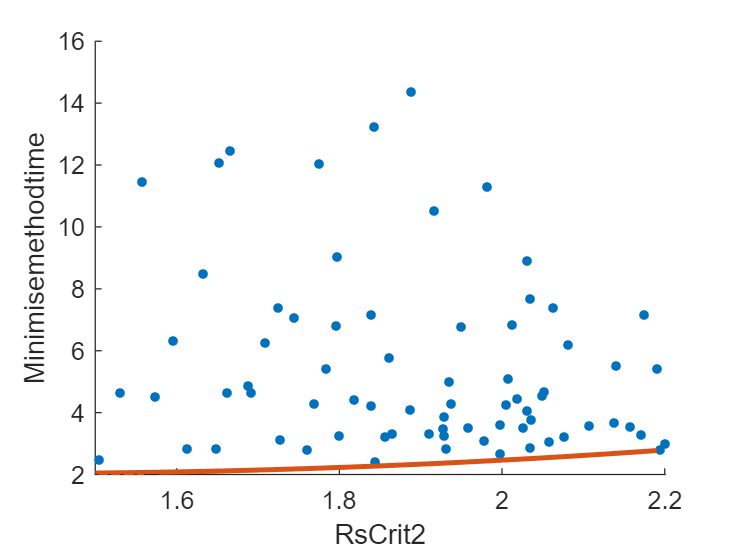

hold on 
fplot(poly2sym(equation), [1.5 2.19], "LineWidth",2)
hold off


allDist = zeros(length(allData(:,1)),3)

allDist =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


for i = 1:length(allData(:,1))
    allDist(i,:) = findMinDist([allData(i,1), allData(i,3)], poly2sym(equation), [1.5 2.19], 0.1, 2.74, 13);
end

allDist(:,1) = normalize(allDist(:,1), 1, "range", [0 1])

allDist =     0.3751    2.1000    2.6173
    0.6692    2.1000    2.6173
    0.8166    2.1000    2.6173
    0.0643    1.8000    2.2285
    0.3949    2.1000    2.6173
    0.0233    2.1000    2.6173
    0.2515    2.0000    2.4646
    0.2712    2.1000    2.6173
    0.0603    1.9000    2.3350
    0.1913    1.6000    2.0852



allDistances = ones(length(indexs),1)

allDistances =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


allDistances(indexs,1) = allDist(:,1);

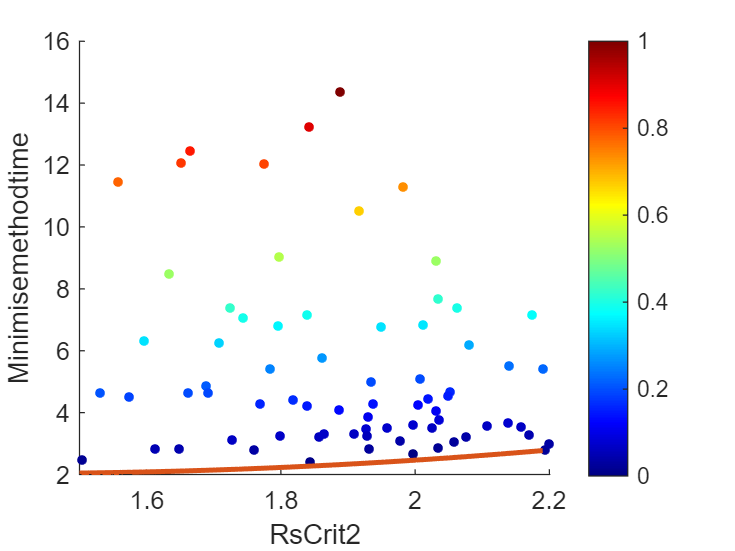

scatter(allData(:,1), allData(:,3), 15,allDist(:,1),'filled')
xlabel("RsCrit2")
ylabel("Minimisemethodtime")
hold on 
fplot(poly2sym(equation), [1.5 2.19], "LineWidth",2)
% for i = 1:length(allDist(:,1))
%     plot([allDist(i,2) allData(i,1)], [allDist(i,3) allData(i,3)], "b-" )
% end

hold off
colormap(jet)
colorbar
caxis([0 1])

function output = findMinDist(point, line, xlims, dx, normAxisX, normAxisY)

xCords = xlims(1):dx:xlims(2);
pointsDist = zeros(1, length(xCords));

for i = 1:length(pointsDist)
    x = xCords(i);
    y = double(subs(line, x));
    pointsDist(i)= sqrt((((y-point(2))/(normAxisY)) ^2) + (((x-point(1))/(normAxisX)) ^2));
end

[minDist, ind] = min(pointsDist);
xMin = xCords(ind);
yMin = double(subs(line, xMin));
output = [minDist, xMin, yMin];

end
